# **Miniprojekt A**

**Mathias Vraa    ***au618687*

## **Formål**

Formålet med denne opgave er at få erfaring med at analysere og bearbejder signaler med Matlab. Signalerne består af tre typer lydfiler: klassisk musik, moderne musik og oplæsning.

## **Implementation**

Hver opgave indeholder introduktion, implementation, resultater og diskussion. Resultater er vist under de grå kode blokke.

### **Opgave 1**

***Find antal samples for alle tre signaler.***

Sample frekvensen er givet som:

fs = 44100; % Hz

Med audioread indlæses hvert lydsignal ind på et variabel. De har alle den samme sample frekvens:

[s1, fs] = audioread("Signal_s1.wav"); % klassisk
[s2, fs] = audioread("Signal_s2.wav"); % moderne
[s3, fs] = audioread("Signal_s3.wav"); % oplæsning

Med funktionen length() tjekkes sample antallet for hvert signal. S1 og s3 er mono signaler, hvilket vil sige de kun har ét lydsignal. S2 er et stereo signal, som betyder at den har to lydsignaler der bliver afspillet i parallel. Length tager højde for dette, da den kun returnere mængden af rows:

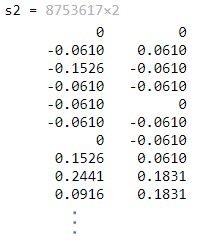

*Figur 1*

n1 = length(s1) % antal

n1 = 4213759

n2 = length(s2) % antal

n2 = 8753617

n3 = length(s3) % antal

n3 = 1270957

Da de alle har samme sample frekvens afhænger længden af spilletiden.

### **Opgave 2**

***Plot alle tre signaler med korrekte tidsakser, og sæt ‘xlabel’, ‘ylabel’ og ‘title’ på.***

Tidsaksen skal bestemmes. Vi kender samplefrekvensen som er samples pr. tid. Den vil vi nu konvertere til tid pr. sample, som gøres med denne formel:

Ts = 1/fs % sekunder

Ts = 2.2676e-05

For at finde spilletiden for signalet, Tn1, ganges mængden af samples, n1, med tid pr. samples, Ts.

Tn1 = n1*Ts % sekunder

Tn1 = 95.5501

Tn2 = n2*Ts % sekunder

Tn2 = 198.4947

Tn3 = n3*Ts % sekunder

Tn3 = 28.8199

Tidaksen kan nu beregnes. Vi starter på 0, springer med Ts og stopper med at springe når Tn1 nåes:

*(For at tage højde for plads nul, skal Tn1 subtraheres med et spring. Ellers bliver signal og tidsakse ikke lige lange og kan derfor ikke plottes)*

t1 = 0:Ts:Tn1-Ts;
t2 = 0:Ts:Tn2-Ts;
t3 = 0:Ts:Tn3-Ts;

Signalerne kan nu plottes.

Det klassiske musik ses nedenunder. Den går meget op og ned. Der er en god fordeling af stille og høje steder i sangen:

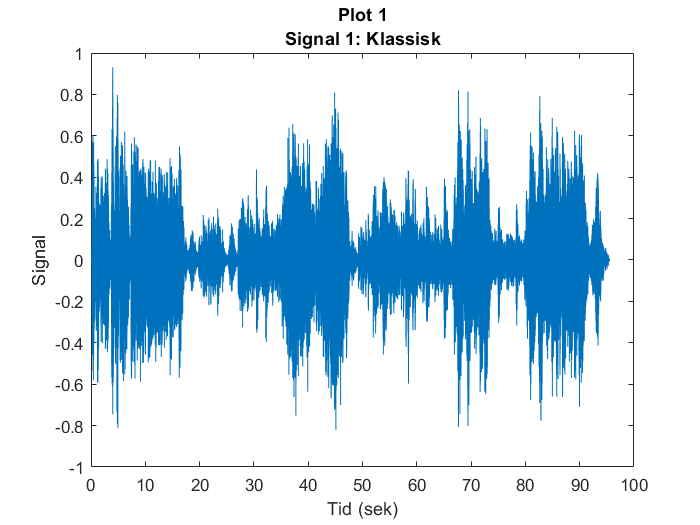

plot(t1,s1)
title("Plot 1" + newline + "Signal 1: Klassisk");
ylabel("Signal");
xlabel("Tid (sek)");

Det moderne musik er meget højlydt hele vejen igennem. Derudover er der også to signaler der spiller på samme tid (det blå signal gemmer sig bag det orange):

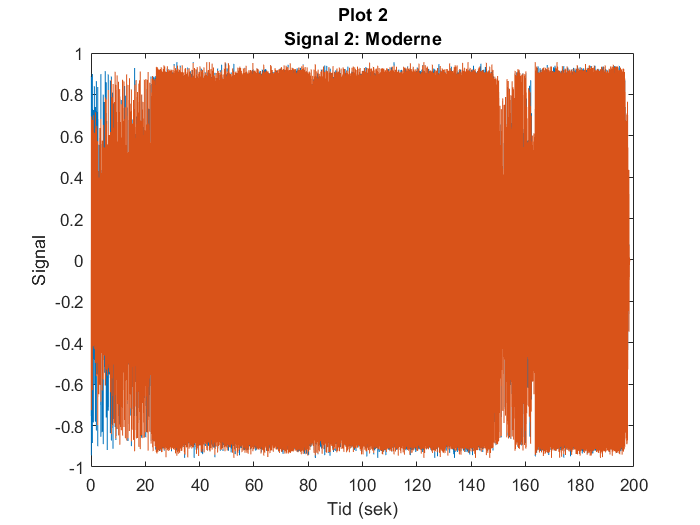

plot(t2,s2)
title("Plot 2" + newline + "Signal 2: Moderne");
ylabel("Signal");
xlabel("Tid (sek)");

I oplæsnings signalet er der en masse pauser hvor signalet ligger ved 0. Det giver mening, da personen som oplæser holder pauser mellem hans sætninger:

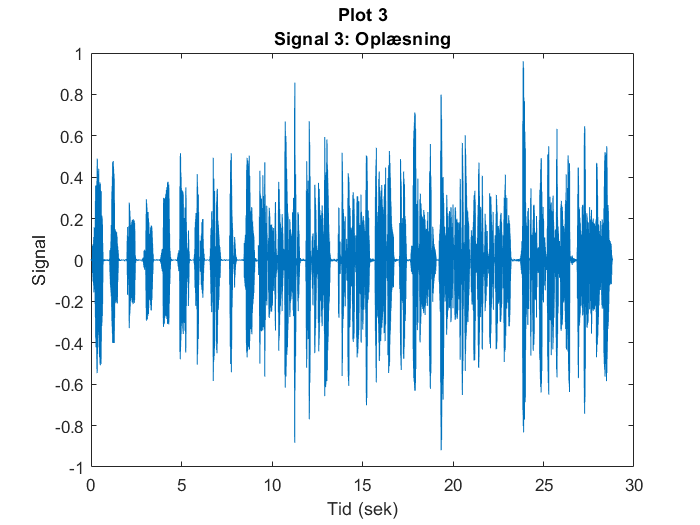

plot(t3,s3)
title("Plot 3" + newline + "Signal 3: Oplæsning");
ylabel("Signal");
xlabel("Tid (sek)");

### **Opgave 3**

***Find for alle tre signaler: max, min, gennemsnit (mean), rms og effekt.***

Max værdi findes med den indbygget funktion max. S2 har to værdier fordi det er stereo. 

max1 = max(s1)

max1 = 0.9306

max2 = max(s2)

max2 =     0.9558    0.9558


max3 = max(s3)

max3 = 0.9600

Minimum værdi beregnes med funktionen min:

min1 = min(s1)

min1 = -0.8205

min2 = min(s2)

min2 =    -0.9558   -0.9558


min3 = min(s3)

min3 = -0.9192

Gennemsnit værdi beregnes med mean funktionen:

mean1 = mean(s1)

mean1 = -4.2834e-05

mean2 = mean(s2)

mean2 = 	1.0e+-4 *

   -0.1941   -0.1938


mean3 = mean(s3)

mean3 = -5.7438e-04

RMS værdi beregnes med rms funktionen:

rms1 = rms(s1)

rms1 = 0.1199

rms2 = rms(s2)

rms2 =     0.3383    0.3548


rms3 = rms(s3)

rms3 = 0.0919

Effekten værdi beregnes med denne formel:

effect1 = (1/n1) * sum(s1.^2)

effect1 = 0.0144

effect2 = (1/n2) * sum(s2.^2)

effect2 =     0.1144    0.1259


effect3 = (1/n3) * sum(s3.^2)

effect3 = 0.0084

Middel-, rms- og effekt værdien er meget høj for det moderne musik (s2) fordi den svinger så voldsomt.

### **Opgave 4**

***Find de tre signalers crest-faktorer, - sammenlign og kommenter.***

Crest faktoren beregnes med denne formel. Resultaterne er i **dB**:

crest1 = 20 * log10(max1/rms1) % dB

crest1 = 17.8006

crest2 = 20 * log10(max2/rms2) % dB

crest2 = 8.8064

crest3 = 20 * log10(max3/rms3) % dB

crest3 = 20.3770

Crest faktoren viser forholdet mellem spidsværdier og den effektive værdi. Dvs. at den angiver hvor ekstreme toppene er i et signal. Det giver derfor mening at s3 (oplæsning) er højest fordi det er det signal der har højest variation af lave og høje toppe. S1 (klassisk) har en lidt mindre variation og s2 (moderne) er meget højlydt hele tiden, og har derfor den mindste variation.

### **Opgave 5**

***Nedsampel s1 med en faktor 4. Plot og lyt – og sammenlign med originalen.***

For at nedsample signalet, s1, samt dens tilhørende tidsakse kan funktionen downsample bruges. Den tager parametrene (x, n), hvor x er signalet og n er den værdi der nedsamples med.

s1_ds4 = downsample(s1,4); % signalet downsamples
t1_ds4 = downsample(t1, 4); % tidsaksen downsamples

Her er et udsnit af hvordan de to signaler lyder. Jeg bruger min egen funktion til at afspiller et par sekunder af det originale og det nedsamplet signal.

myplayer(s1,3.5,fs) % original:
myplayer(s1_ds4,3.5,fs/4) % nedsamplet:

Jeg plotter det nedsamplet signal:

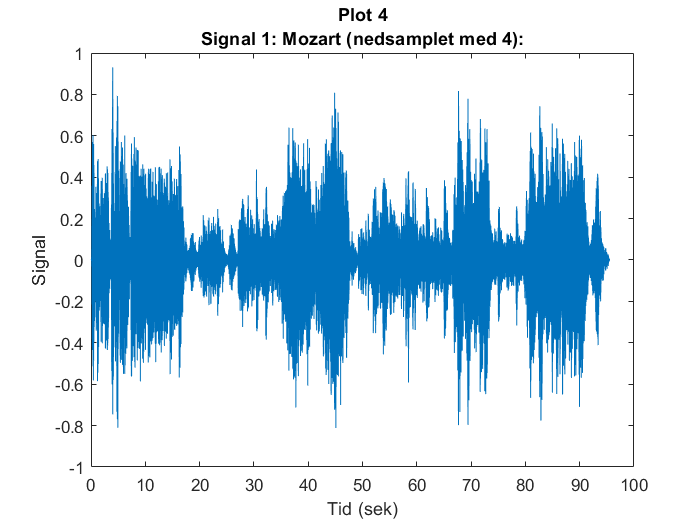

plot(t1_ds4, s1_ds4)
title("Plot 4" + newline + "Signal 1: Mozart (nedsamplet med 4):");
xlabel("Tid (sek)");
ylabel("Signal");

### **Opgave 6**

***Beskriv forskellen mellem originalen og den nedsamplede version.***

Når man plotter kan man ikke se den store forskel mellem de to signaler. Det kan man dog når man afspiller dem. Sammenlignet med den nedsamplet er originalen er meget klar og tydelig. Grunden er, at når man nedsampler, tager man udsnit fra det originale signal. I vores tilfælde tager vi udsnit i en opløsning der er 4 gange lavere end originalen - det kan ses på billedet nedenunder:

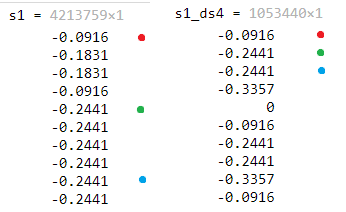

*Figur 2*

Groft sagt, går man altså glip af en fjerdedel af sangen, da vi ikke høre de samples imellem vores udsnit.

### Opgave 7

***Sammenlign de to stereo-kanaler i s2 – beskriv forskelle og ligheder.***

Jeg adskiller først de to signaler fra hinanden:

s2_1 = s2(:,1);
s2_2 = s2(:,2);

Nu kan de plottes hver for sig:

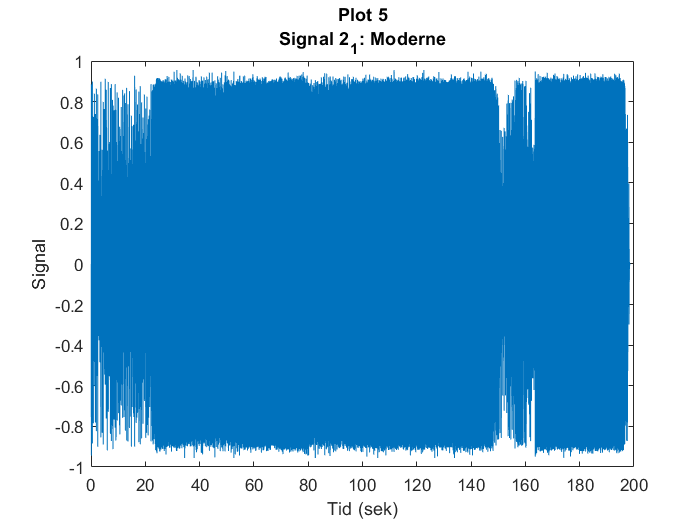

plot(t2,s2_1)
title("Plot 5" + newline + "Signal 2_1: Moderne");
ylabel("Signal");
xlabel("Tid (sek)");

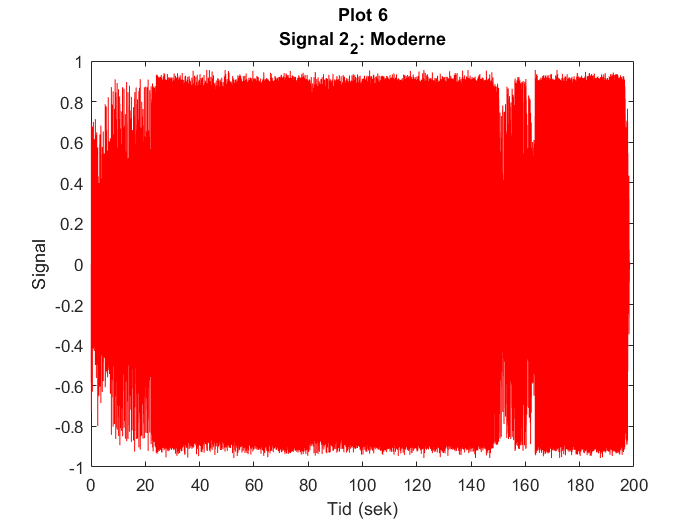


plot(t2,s2_2,"r")
title("Plot 6" + newline + "Signal 2_2: Moderne");
ylabel("Signal");
xlabel("Tid (sek)");

De to signaler ligner hinanden meget. De første 20 sekunder er der hvor der er størst forskel. Signal s2_1 har nogle større spikes, hvor imod s2_2 ramper op. Når man optager stereo lyd er det konvention at bruge to ens mikrofoner der er lige langt væk fra en lyd source. Når de to klips er spillet parallelt giver det lyden en dybde som mono ikke har. Det er altså forklaring for hvorfor de to signaler ser så ens ud.

### Opgave 8

***Kvantiser s2 (venstre kanal) med 4 bit (brug egen funktion eller den på BB). Plot og lyt, - sammenlign med originalen og kommenter.***

Jeg bruger funktionen quantizeN til at kvantisere signal s2_1 med 4 bits.

s2_1q = quantizeN(s2_1,4);

Jeg sammenligner afspilningen med originalen:

myplayer(s2_1,5,fs) % original
myplayer(s2_1q,5,fs) % kvansiseret

Jeg plotter resultatet:

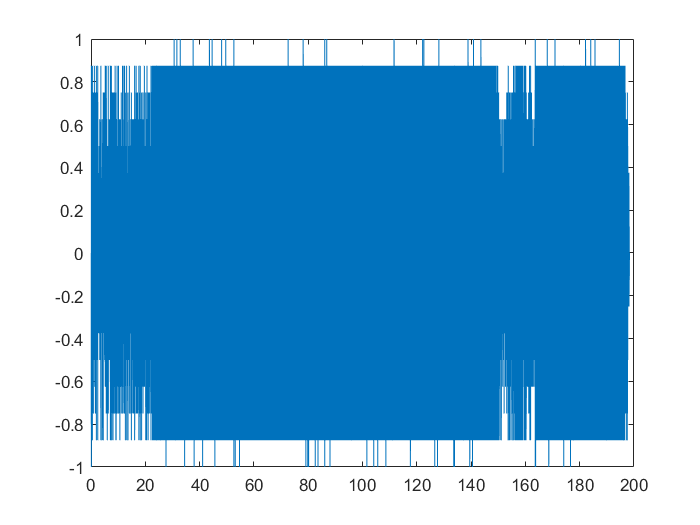

plot(t2, s2_1q)
title("Plot 7" + newline + "Signal 2_1q: Moderne");
ylabel("Signal");
xlabel("Tid (sek)");

Det kvantiseret plot se meget kvadratisk ud sammenlignet med den originale. Lyden fra det kvantiseret signal lyder på en måde som det skal, bortset fra at der er en forfærdelig masse static. 

Grunden til at plottet ser så kvadratisk ud er at y værdierne er blevet konverteret til 4 bit. Det vil sige at der er færre punkter langs y-aksen som den kan påtage sig. Mange af de y værdier som er tæt på hinanden vil derfor bare blive plottet på det samme sted. Der er derfor en masse huller på y aksen som signalet ikke kan plottes på. Lyden lyder derfor også dårligere.

### Opgave 9

***Lav et ‘fade out’ på s3 over den sidste tredjedel med en eksponentielt aftagende envelope, hvor amplituden ved slutningen er aftaget til 5%.***

I denne opgave skal den sidste tredjedel af signal 3 fades eksponentiel ud til det er aftaget med 5%.

For at gøre opgaven nemmere laver jeg først to variabler der indeholder indexet for to tredjedele og én tredjedel af signalet s3.

twothird = round(n3*(2/3))

twothird = 847305

onethird = round(n3*(1/3))

onethird = 423652

Jeg bruger funktionen logspace til at genere en logaritmisk aftagende array. Denne array skal bruges til at ganges på den sidste tredjedel af signalet (parameter 3). Logspace(a,b,n), hvor n er steps imellem dekaderne 10^a og 10^b. Den går altså fra, 10^0 = **1**, til 10^log10(0.05) = **0.05**. Jeg transposer med ' for at få svaret som kolonne.

fade_log = logspace(0,log10(0.05),onethird)';

Jeg støber nu de første to tredjedele af s3, sammen med den sidste tredjedel af s3 ganget med min fade log. Derefter plottes det fadet signal.

s3_fade = [s3(1:twothird); s3(twothird+1:end).*fade_log];
plot(s3_fade);

Jeg afspiller den sidste tredjedel af mit fadet signal.

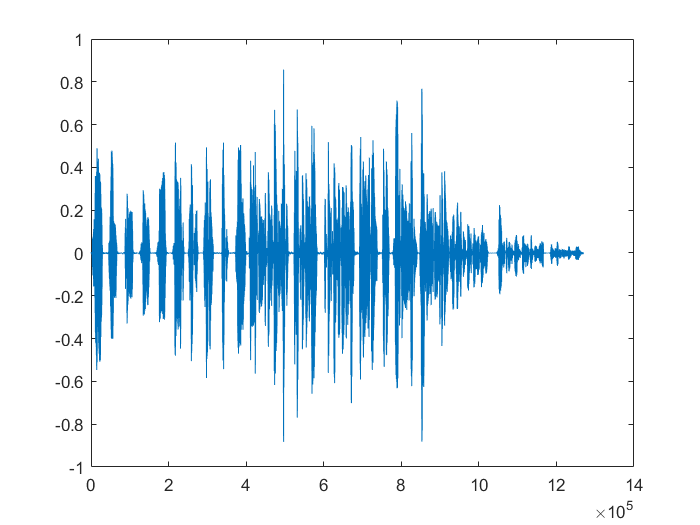

myplayer(s3_fade(twothird:end),5,fs)

Kigger man på plottet, kan man tydeligt se at det fader ud i slutningen. Man kan også høre det hvis man lytter til signalet.

### Opgave 1.15

***Konstruer et ekko-signal. Ekkoet skal i første omgang være på 150ms. Lyt til signalet. Varier dernæst ekkoet til 40ms og 300ms. Lyt igen og kommenter.***

Samples pr. delay beregnes:

echo_delay = 0.15; % % 0.15s, 0.04s og 0.3s
echo_n = echo_delay / Ts % samples pr. delay

echo_n = 6615

Når der smides et echo på et signal, bliver spilletiden udvidet med længden af dette delay. Jeg laver derfor et nyt signal bestående af nuller med længden af delayet og det originale signal:

s3_echo = zeros(1,echo_n+n3); % nyt tomt array

Den første del af echosignalet plusses med s3. S3 bliver derefter adderet oven på den sidste del af echo signalet. S3 kommer derfor til at ligge oven på sig selv med en forskydelse på delay. Det vil derfor skabe en echo effekt:

s3_echo(1:n3) = s3'; % s3 plusses på den første del
s3_echo(echo_n+1:end) = s3_echo(echo_n+1:end) + s3'; % s3 plusses på den sidste del

myplayer(s3_echo,5,fs)

Her er et billede der forklarer det visuelt:

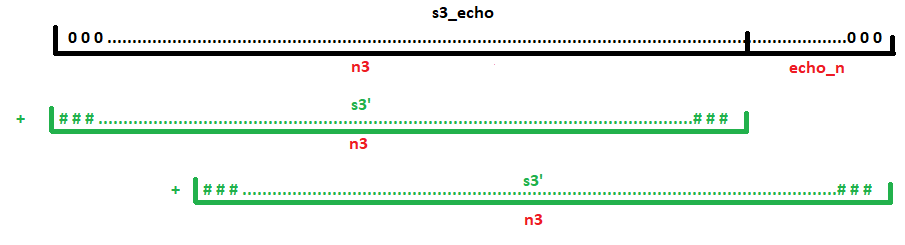

*Figur 3*

Echo signalet er vist med sort, array længder er vist med rødt og de to s3 signaler der adderes på echo signalet er vist med grøn.

Lytter man til signalet kan man høre et ekko. Med et echo delay på 0.04s lyder det som to personer der snakker oven i hinanden, fordi delayet er så kort. Ved 0.15s og 0.3s lyder det som et delay.

## **Konklusion**

Alle opgaver er blevet løst og jeg har fået en dybere forståelse for hvordan man bruger Matlab til at bearbejde signaler. Matlab gør det generelt meget simpelt at analysere signaler, fordi det er lavet til at håndtere større mængder data. Matlab har også en masse brugbare indbygget funktioner, så man ikke skal regne alting selv.